layers = [imageInputLayer([224 224 3]);
          convolution2dLayer(5,16,'Stride',1,'Padding',1);
          batchNormalizationLayer;
          reluLayer();
          maxPooling2dLayer(2,'Stride',2);
          convolution2dLayer(5,32,'Stride',1,'Padding',1);
          batchNormalizationLayer;
          reluLayer();
          maxPooling2dLayer(2,'Stride',2);
          convolution2dLayer(5,64,'Stride',1,'Padding',1);
          batchNormalizationLayer;
          reluLayer();
          fullyConnectedLayer(3);
          softmaxLayer();
          classificationLayer()];

analyzeNetwork(layers)

parentDir = './';
dataDir = 'data';

allImages = imageDatastore(fullfile(parentDir,dataDir),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 130


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 32


options1 = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',7,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:26 |       33.33% |       56.25% |       1.1843 |       0.9631 |      1.0000e-04 |
|       2 |          10 |       00:00:48 |       86.67% |       78.12% |       0.4209 |       0.7333 |      1.0000e-04 |
|       3 |          20 |       00:01:11 |      100.00% |       87.50% |       0.0145 |       0.4687 |      1.0000e-04 |
|       4 |          30 |       00:01:34 |      100.00% |       87.50% |       0.0847 |       0.3364 |      1.0000

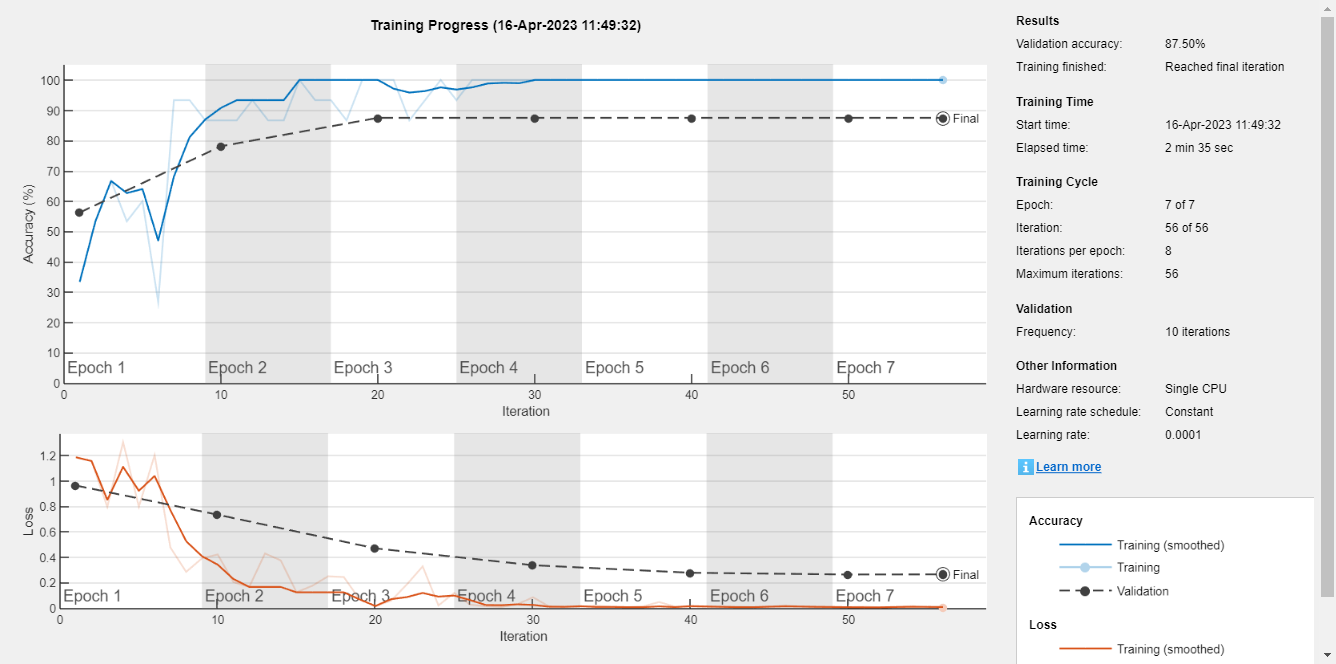

trained_s = trainNetwork(imgsTrain,layers,options1);

[YPred_s,probs_s] = classify(trained_s,imgsValidation);
accuracy_s = mean(YPred_s==imgsValidation.Labels);
disp(['Accuracy using sgdm: ',num2str(100*accuracy_s),'%'])

Accuracy using sgdm: 87.5%


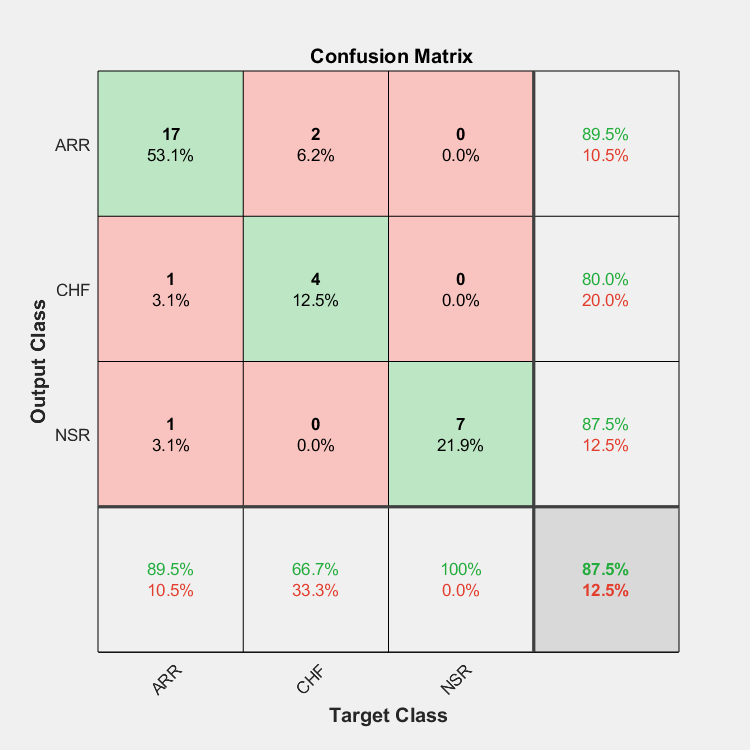

plotconfusion(imgsValidation.Labels,YPred_s)

options3 = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |       33.33% |       56.25% |       1.1843 |       0.9631 |      1.0000e-04 |
|       2 |          10 |       00:00:34 |       86.67% |       78.12% |       0.4209 |       0.7333 |      1.0000e-04 |
|       3 |          20 |       00:00:56 |      100.00% |       87.50% |       0.0145 |       0.4687 |      1.0000e-04 |
|       4 |          30 |       00:01:19 |      100.00% |       87.50% |       0.0847 |       0.3364 |      1.0000

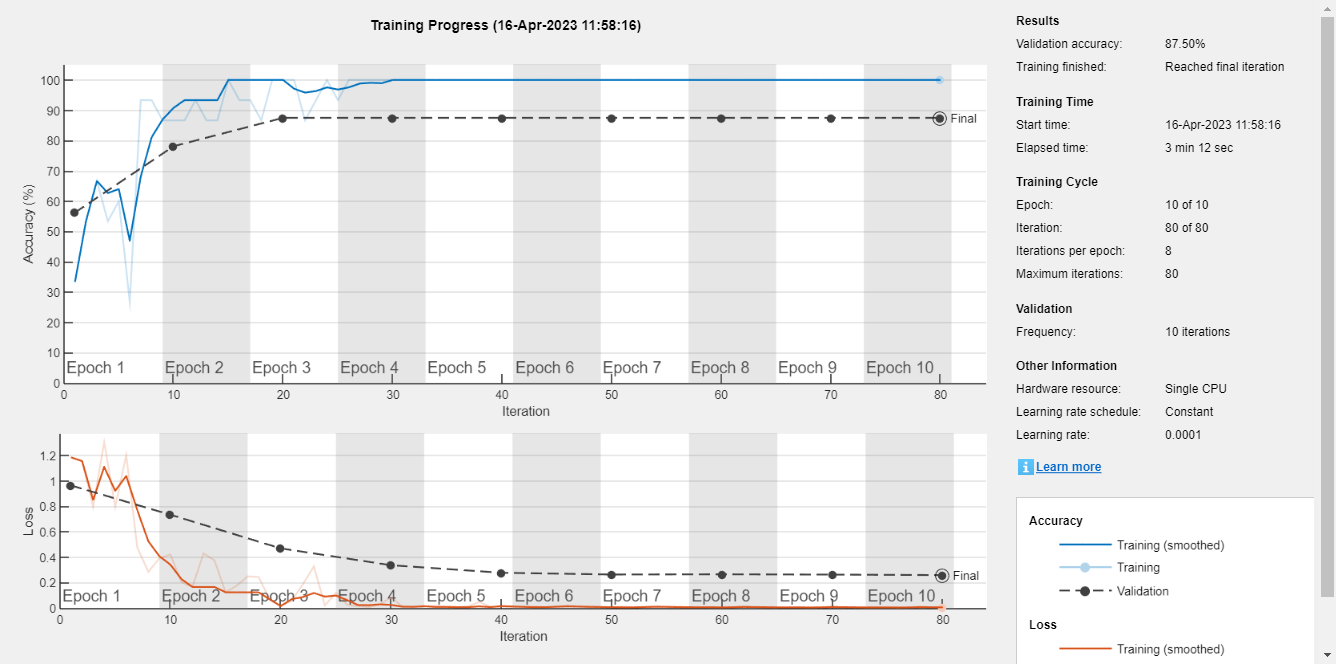

trained_s1 = trainNetwork(imgsTrain,layers,options3);

[YPred_s1,probs_s1] = classify(trained_s1,imgsValidation);
accuracy_s1 = mean(YPred_s1==imgsValidation.Labels);
disp(['Accuracy using sgdm: ',num2str(100*accuracy_s1),'%'])

Accuracy using sgdm: 87.5%


plotconfusion(imgsValidation.Labels,YPred_s1)

options2 = trainingOptions("adam", ...
    'MiniBatchSize',15,...
    'MaxEpochs',7,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |       33.33% |       59.38% |       1.1843 |       2.3516 |      1.0000e-04 |
|       2 |          10 |       00:00:30 |       80.00% |       81.25% |       0.3585 |       0.8546 |      1.0000e-04 |
|       3 |          20 |       00:00:52 |      100.00% |       81.25% |       0.0008 |       0.6068 |      1.0000e-04 |
|       4 |          30 |       00:01:14 |      100.00% |       84.38% |       0.0335 |       0.5112 |      1.0000

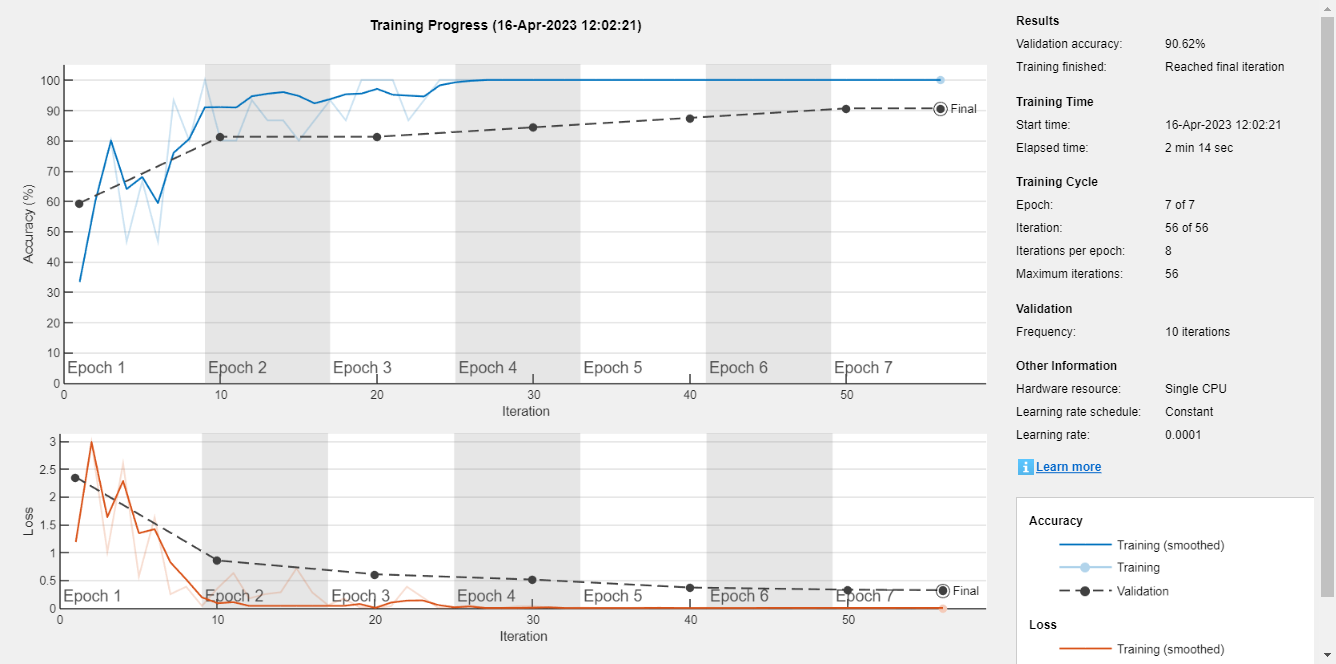

trained_a = trainNetwork(imgsTrain,layers,options2);

[YPred_a,probs_a] = classify(trained_a,imgsValidation);
accuracy_a = mean(YPred_a==imgsValidation.Labels);
disp(['Accuracy using adam: ',num2str(100*accuracy_a),'%'])

Accuracy using adam: 90.625%


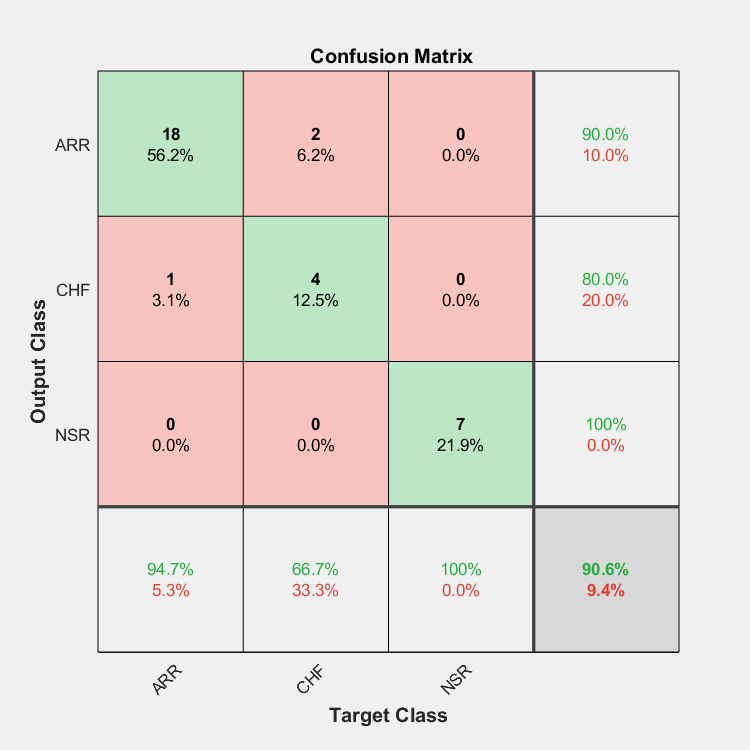

plotconfusion(imgsValidation.Labels,YPred_a)

options4 = trainingOptions("adam", ...
    'MiniBatchSize',15,...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       33.33% |       59.38% |       1.1843 |       2.3516 |      1.0000e-04 |
|       2 |          10 |       00:00:32 |       80.00% |       81.25% |       0.3585 |       0.8546 |      1.0000e-04 |
|       3 |          20 |       00:00:55 |      100.00% |       81.25% |       0.0008 |       0.6068 |      1.0000e-04 |
|       4 |          30 |       00:01:18 |      100.00% |       84.38% |       0.0335 |       0.5112 |      1.0000

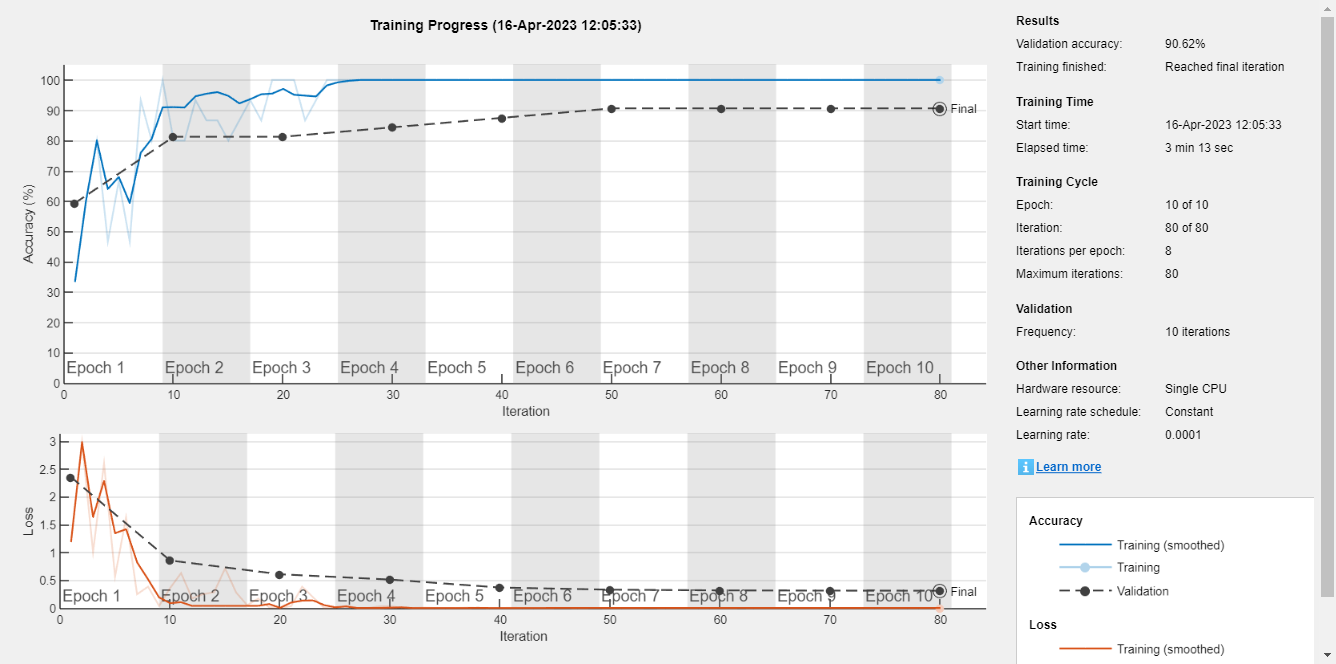

trained_a1 = trainNetwork(imgsTrain,layers,options4);

[YPred_a1,probs_a1] = classify(trained_a1,imgsValidation);
accuracy_a1 = mean(YPred_a1==imgsValidation.Labels);
disp(['Accuracy using adam: ',num2str(100*accuracy_a1),'%'])

Accuracy using adam: 90.625%


plotconfusion(imgsValidation.Labels,YPred_a1)

cm_s = confusionmat(imgsValidation.Labels,YPred_s)

cm_s =     17     1     1
     2     4     0
     0     0     7


cmt_s = cm_s';
diagonal_s = diag(cmt_s);

sum_r = sum(cmt_s,2);
precision_s = diagonal_s./sum_r;
overall_precision_s = mean(precision_s)

overall_precision_s = 0.8566

sum_c = sum(cmt_s,1);
recall_s = diagonal_s./sum_c';
overall_recall_s = mean(recall_s)

overall_recall_s = 0.8538

f1_score_s = (2*overall_precision_s*overall_recall_s)/(overall_recall_s + overall_precision_s)

f1_score_s = 0.8552

s_p = [accuracy_s*100 overall_precision_s*100 overall_recall_s*100 f1_score_s*100]

s_p =    87.5000   85.6579   85.3801   85.5188


cm_s1 = confusionmat(imgsValidation.Labels,YPred_s1)

cm_s1 =     17     1     1
     2     4     0
     0     0     7


cmt_s1 = cm_s1';
diagonal_s1 = diag(cmt_s1);

sum_r1 = sum(cmt_s1,2);
precision_s1 = diagonal_s1./sum_r1;
overall_precision_s1 = mean(precision_s1)

overall_precision_s1 = 0.8566

sum_c1 = sum(cmt_s1,1);
recall_s1 = diagonal_s1./sum_c1';
overall_recall_s1 = mean(recall_s1)

overall_recall_s1 = 0.8538

f1_score_s1 = (2*overall_precision_s1*overall_recall_s1)/(overall_recall_s1 + overall_precision_s1)

f1_score_s1 = 0.8552

s_p1 = [accuracy_s1*100 overall_precision_s1*100 overall_recall_s1*100 f1_score_s1*100]

s_p1 =    87.5000   85.6579   85.3801   85.5188


cm_a = confusionmat(imgsValidation.Labels,YPred_a)

cm_a =     18     1     0
     2     4     0
     0     0     7


cmt_a = cm_a';
diagonal_a = diag(cmt_a);

sum_r = sum(cmt_a,2);
precision_a = diagonal_a./sum_r;
overall_precision_a = mean(precision_a)

overall_precision_a = 0.9000

sum_c = sum(cmt_a,1);
recall_a = diagonal_a./sum_c';
overall_recall_a = mean(recall_a)

overall_recall_a = 0.8713

f1_score_a = (2*overall_precision_a*overall_recall_a)/(overall_recall_a + overall_precision_a)

f1_score_a = 0.8854

a_p = [accuracy_a*100 overall_precision_a*100 overall_recall_a*100 f1_score_a*100]

a_p =    90.6250   90.0000   87.1345   88.5441


cm_a1 = confusionmat(imgsValidation.Labels,YPred_a1)

cm_a1 =     18     1     0
     2     4     0
     0     0     7


cmt_a1 = cm_a1';
diagonal_a1 = diag(cmt_a1);

sum_r1 = sum(cmt_a1,2);
precision_a1 = diagonal_a1./sum_r1;
overall_precision_a1 = mean(precision_a1)

overall_precision_a1 = 0.9000

sum_c1 = sum(cmt_a1,1);
recall_a1 = diagonal_a1./sum_c1';
overall_recall_a1 = mean(recall_a1)

overall_recall_a1 = 0.8713

f1_score_a1 = (2*overall_precision_a1*overall_recall_a1)/(overall_recall_a1 + overall_precision_a1)

f1_score_a1 = 0.8854

a_p1 = [accuracy_a1*100 overall_precision_a1*100 overall_recall_a1*100 f1_score_a1*100]

a_p1 =    90.6250   90.0000   87.1345   88.5441


x = categorical({'accuracy','precision','recall','f1score'});
x = reordercats(x,{'accuracy','precision','recall','f1score'});
b = bar(x, [s_p;a_p]')

b =   1×2 Bar array:

    Bar    Bar


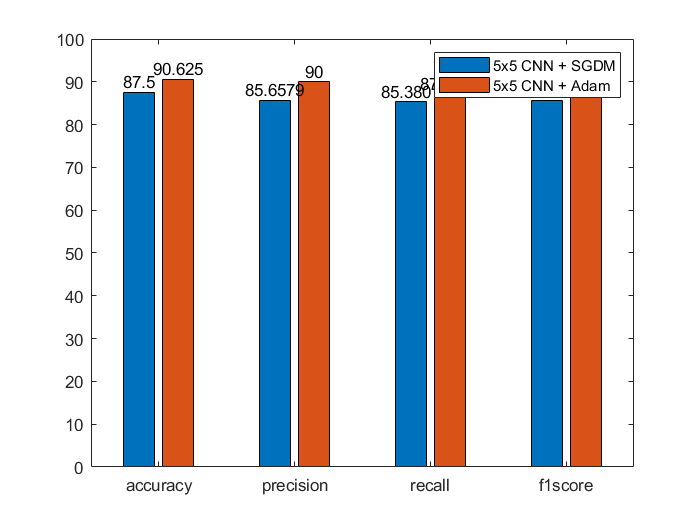

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(b(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
legend('5x5 CNN + SGDM','5x5 CNN + Adam')

x = categorical({'accuracy','precision','recall','f1score'});
x = reordercats(x,{'accuracy','precision','recall','f1score'});
b1 = bar(x, [s_p1;a_p1]')

b1 =   1×2 Bar array:

    Bar    Bar


xtips3 = b1(1).XEndPoints;
ytips3 = b1(1).YEndPoints;
labels3 = string(b1(1).YData);
text(xtips3,ytips3,labels3,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips4 = b1(2).XEndPoints;
ytips4 = b1(2).YEndPoints;
labels4 = string(b1(2).YData);
text(xtips4,ytips4,labels4,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
legend('5x5 CNN + SGDM','5x5 CNN + Adam')

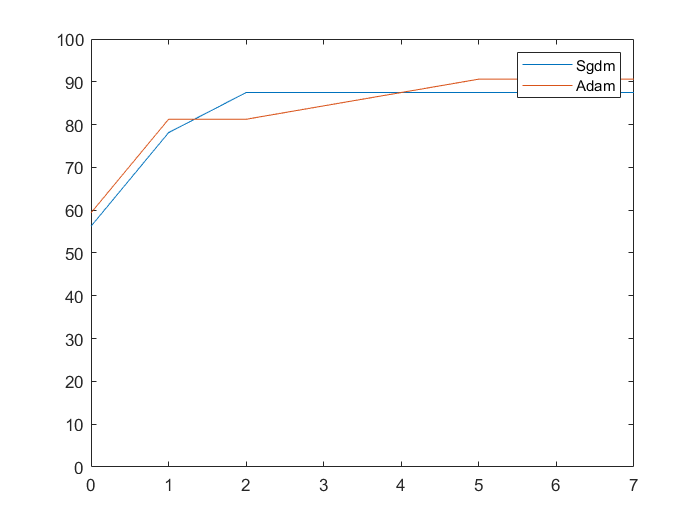

train_s7x = [0 1 2 3 4 5 6 7];
train_s7y = [56.25 78.12 87.5 87.5 87.5 87.5 87.5 accuracy_s*100];
train_a7y = [59.38 81.25 81.25 84.38 87.50 90.62 90.62 accuracy_a*100];
plot(train_s7x,train_s7y)
hold on
plot(train_s7x,train_a7y)
xlim([0 7])
ylim([0 100])
legend('Sgdm','Adam')
hold off

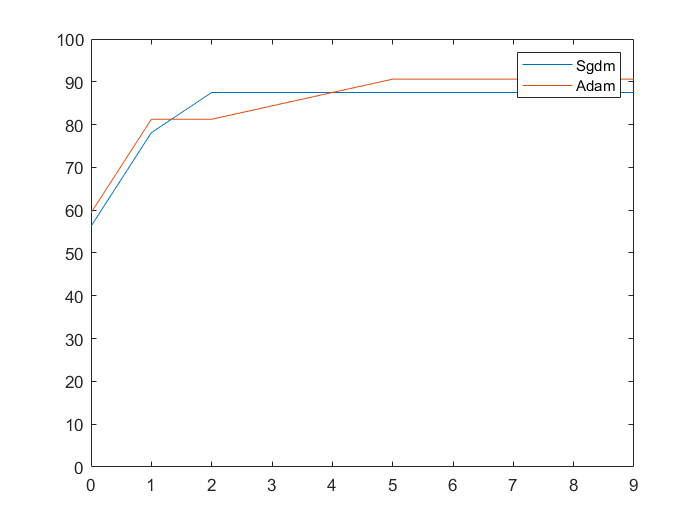

train_s1x = [0 1 2 3 4 5 6 7 8 9];
train_s1y = [56.25 78.12 87.5 87.5 87.5 87.5 87.5 87.5 87.5 accuracy_s1*100];
train_a1y = [59.38 81.25 81.25 84.38 87.50 90.62 90.62 90.62 90.62 accuracy_a1*100];
plot(train_s1x,train_s1y)
hold on
plot(train_s1x,train_a1y)
xlim([0 9])
ylim([0 100])
legend('Sgdm','Adam')
hold off